# **GEO4-1424A  - Applied Geophysics 2021**

# **Seismic Processing Lab**

# ***Exercise 2 - Post-Stack Zero-offset Migration using a Velocity Model***

## Contact: Ivan Vasconcelos (I.Vasconcelos@uu.nl), Leon Diekmann (L.D.Diekmann@uu.nl)

In this exercise, you will migrate seismic data for some simple cases and for the * tripli * dataset.

** Migration of point diffractors **

 You will be looking at a zero-offset section. It could be that this  data were obtained by actually deploying co-located sources and  receivers (*e.g., common in GPR applications!*). It could also be that the zero-offset data resulting from  NMO  correction and stacking over CMP gathers, as was executed in **Exercise 3**.

 The data shows the primary reflections from two point diffractors.  These two points in the subsurface lead to hyperbolic reflections in the zero-offset gather. For this dataset:     

- Change to the directory U:\MATLAB\Reflection_Seismics\ with the **cd** command. 

-  Reload the path definition file: ** path(pathdef)**. 

-   Read the dataset * points.segy * (SEGY format) from the *...\data\* directory into the Matlab workspace. You do not need to store the headers. 

*                                                                                                                Example of a zero-offset section with two point diffractors*

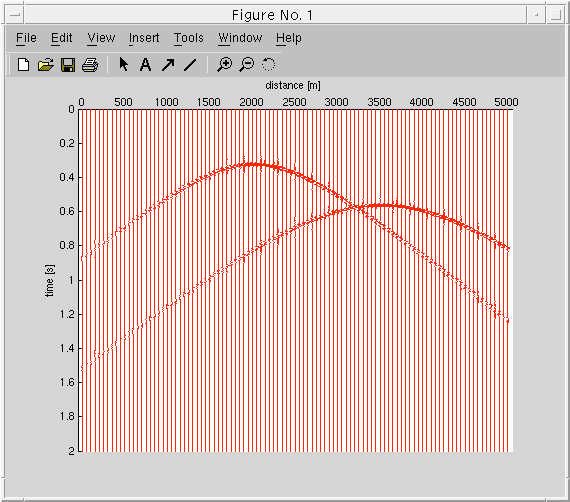

The parameters needed for the *points.segy* dataset are given in the table below. 

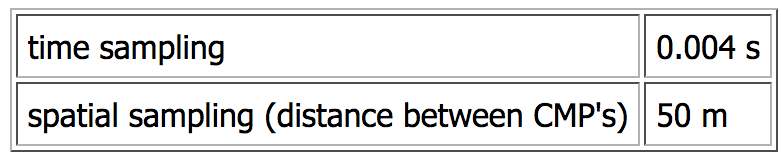

- Using these parameters, plot the dataset with the proper numbers on the axes (time on vertical and distance on horizontal axis).

 Next, you need to migrate this dataset, that means you need to focus the energy to where it comes from: in this case the apices. For this focussing, you need to have an estimate of the velocity. A first estimate of the velocity can be made by looking at the slope of the tails of the hyperbolae.   

-  Make this estimate from the plot you have made above. 

 For the migration, you need to use the CREWES command **kirk_mig2 **. This migration routine is based on Kirchhoff-migration:      

-  Find out how ** kirk_mig2 ** works. You do not need to worry about the input argument 'params': the defaults are fine. 

 This routine needs a velocity and you need to find out out which (constant) velocity is appropriate for focussing the seismic energy to the apices. Therefore:   

-  Start migrating the data with **kirk_mig2** with a velocity slightly smaller than your estimate above, and inspect your result. 

 The result should be "under-migrated". When the velocity is too high, the result is "over-migrated" (a "migration-smile"). Now: 

-  Repeatedly adapt the velocity and migrate the data until they have been migrated well.

##  Key Questions: Point-Diffractors 

-  Which velocity did you find ? Answer [ ........ m/s ] 

-  Does the velocity found by migration correspond to the velocity you estimated from the response of the point diffractors on the zero-offset section, using the slope at the tails of the hyperbolae ?? If the velocities are much different, how much are they different and how would you explain this difference ? 

 When you yourself are satisfied with your answers:  → [Let the instructor check your result]

** Migration of dipping reflectors **

 This dataset consists of a zero-offset section of a few dipping reflectors.

- Read the dataset * planes.segy * from the *U:\MATLAB\Reflection_Seismics\data\* directory into the Matlab memory/workspace. You do not need to store headers.

 The parameters needed for this dataset are given in the table below. 

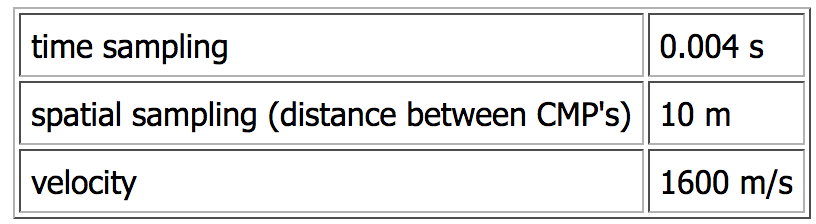

-  Using these parameters, plot the dataset with the proper numbers on the axes (time on vertical and distance on horizontal axis).

 Next, you need to migrate this dataset, i.e., focus the energy to where it comes from. Again you need to use the CREWES command **kirk_mig2 **.     

-  Migrate the dataset 

## Key Questions: Dipping Reflector [1/2] 

-  Explain the differences between the migrated result and the un-migrated zero-offset dataset. 

 Finally, if you would change the velocity to 2000 m/s, what would you expect to happen ?     

-  Carry out the migration with the higher velocity 

## Key Questions: Dipping Reflector [2/2] 

-  Where do you see the difference(s) between the 'overmigrated' result with too high velocity and the previous one which used the correct velocity? How do you explain the difference(s)? 

** Migration of stacked dataset ***** tripli *** 

 This dataset is the zero-offset stack you created in the previous exercise. At the end of **Exercise 3**, you saved the zero-offset section as a **.mat* file, together with the velocity model. Also, you noted the CMP-spacing. 

-  Import the stacked dataset and velocity model into the Matlab workspace with the ** load ** command. 

-  Plot the stacked or pseudo-zero-offset section with the  right numbers on the axes (time on vertical and distance  on  horizontal); 

-  Plot the velocity model with **imagesc**, with a colorbar; 

- Migrate the *tripli* dataset using your velocity model (so *not* with a constant velocity). 

-  Plot the result on your screen, taking care of the fact  that you created another time and space vector for the migration result  (see ** kirk_mig2 **). 

-  Also plot the non-migrated section on your screen. 

##  Key Question: Tripli Dataset 

-  Compare the Tripli Dataset before and after migration: Where do you see the difference(s)? And how do you explain them ? 

  → [Let the instructor check your result]

** Updating the velocity model for dataset ***** tripli *** 

 After the migration, you have seen for the first time what the subsurface structure is really like. However, what you may realize is that the velocity model you have found from velocity analysis in **Exercise 3** is far from consistent with this image: ideally, the RMS-velocities should follow the structure.   In order to improve the migration result, you are going to update the velocity model using the extra knowledge of the subsurface structure, and re-process the data, starting from the CMP gathers again: 

-  First save both your reflectivity image and your velocity model (you will need it for comparison at the end); 

-  With the extra knowledge of the subsurface structure,  determine the times at which the reflections occur at the CMP's you have chosen for velocity analysis; 

-  Using these times, select the right reflections in the CMP gathers that need to be aligned and neglect the other reflections  (since they come from the sides of the structure!) 

-  For each CMP, use ** nmo_vt ** (with * vlog.m *) again to inspect whether the desired reflections are properly aligned; 

-  Update * velocitypicks.m *, generate the lateral velocity model and inspect its consistency with your reflectivity image; 

-  Then NMO, mute, stack and migrate the * tripli * dataset with the updated velocity model; 

-  Plot the migrated section again with the right numbers on the axes (time on vertical and distance on horizontal); 

-  Plot the velocity model again with **imagesc**, with a colorbar; 

-  Now plot also your previous section and velocity model, and 

##  Key Question: Velocity Model Updating 

-  Compare the migrated sections and velocity models before and after updating: How has the updating affected your results ? Where specifically has it improved ? 

 When you yourself are satisfied with your answers:  → [Let the instructor check your result]

## ** Extra **

 Through the different exercises you have gone all the way from  shotgather data to migrated images. We discussed many aspects of a  realistic processing flow, but not all. A few additional aspects relevant for the upcoming field data (next  exercise) are the following: 

For reflection imaging we only use the primary P-wave reflections in the data. However, data recorded in the field contain many other arrivals like surface waves, air waves, converted waves and refractions.  Conveniently, much of the unwanted arrivals are recorded at different frequencies than the primary P-wave reflections. Hence, the field recording can already largely be cleaned up by bandpass filtering. Studying the frequency content of the data is done with the command ** f_plot**. 

A good approach is to first select a portion of the data dominated by surface waves and to study the frequency content with ** f_plot**.  Next, the same can be done with a portion of the data dominated by reflections. After this study, a frequency band can be defined that largely retains the reflections, but suppresses the surface waves.  The bandpass filtering is achieved with the command ** f_filt4 **.

 In field data there will be reflections from very shallow  interfaces and from quite deep interfaces.  For these different reflections, the difference in amplitudes can be  tremendous, due to differences in reflection and transmission  coefficients, anelastic losses and geometrical spreading. The first  quantities are part of the subsurface state. The latter quantity  (geometrical spreading) can be considered an acquisition footprint that  one needs to correct for by boosting the amplitudes of the later  arrivals. This can be done with the function ** gain**. Note that this function is a 1D gain (only gain as function of time),  working only at a single trace. Hence, a loop over traces needs to be  used to apply the gain to a complete shotgather, or entire dataset.  Also take care that the input time vector has the same size as the input trace. E.g., if the input trace is 1001 by 1 samples (a column vector), then the time vector should also be 1001 by 1 samples.

 Finally, the migrated images we obtained in these exercises were still in time, instead of in depth. The estimated velocity model can be used to do the conversion from time to depth. For you available is the  function ** t2d **.